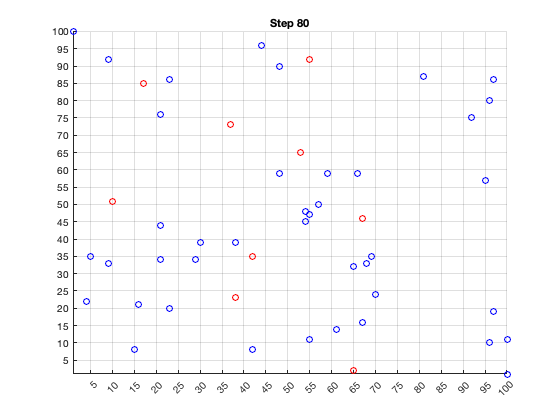

% Parameters
gridSize = 100;
nAgents = 50; % Number of agents
agentPositions = ceil(rand(nAgents, 2) * gridSize); % Random initial positions
agentStates = zeros(nAgents, 1); % 0 = Susceptible, 1 = Infected, 2 = Recovered
infectionDuration = 70; % Duration an agent stays infected
agentInfectionTime = zeros(nAgents, 1); % Track infection duration


% Initialize some agents as infected
initiallyInfected = randperm(nAgents, 20);
agentStates(initiallyInfected) = 1;
agentInfectionTime(initiallyInfected) = infectionDuration;

% Number of simulation steps
nSteps = 80;

% Set up video writer
videoFile = 'epidemicSimulation.avi'; % Output video file name
writer = VideoWriter(videoFile);
open(writer);

% Simulation loop
for step = 1:nSteps
    % Plotting setup
    figure(1);
    clf; % Clear figure
    hold on; % Hold on to plot multiple data sets
    axis([1 gridSize 1 gridSize]); % Set axis limits
    grid on; % Turn on grid
    set(gca, 'xtick', 0:5:gridSize, 'ytick', 0:5:gridSize); % Grid lines

    % Copy current positions and states for concurrent updates
    newPositions = agentPositions;
    newStates = agentStates;
    
    % Update the agents
    for i = 1:nAgents
        if agentInfectionTime(i) > 0
            % Agent is currently infected
            agentInfectionTime(i) = agentInfectionTime(i) - 1;
            if agentInfectionTime(i) == 0
                newStates(i) = 2; % Recover
            end
        end

        % Random walk: move agent to a new position
        pos = agentPositions(i, :);
        new_pos = pos + randi([-3, 3], 1, 2);
        new_pos = max(min(new_pos, gridSize), 1); % Keep within bounds
        newPositions(i, :) = new_pos;

        


        % Cellular automata
        if newStates(i) == 0
            % Check number of surrounding infected
            nSurrounding = 0;
            for surrounding_x = -2:2
                for surrounding_y = -2:2
                    check_x = new_pos(1) + surrounding_x;
                    check_y = new_pos(2) + surrounding_y;
                    is_occupied = ismember([check_x check_y], agentPositions, 'rows');
                    nSurrounding = nSurrounding + (is_occupied && newStates(find(is_occupied), 1) == 1);
                end
            end

            % Probability of spreading infection
            if nSurrounding == 0
                infectionProbability = 0;
            elseif nSurrounding <= 2
                infectionProbability = 0.2;
            elseif nSurrounding <= 4
                infectionProbability = 0.5;
            elseif nSurrounding <= 6
                infectionProbability = 0.8;
            else
                infectionProbability = 0.9;
            end
            
            % Infect
            if rand <= infectionProbability
                newStates(i) = 1;
                agentInfectionTime(i) = infectionDuration;
            end

        end


        % Update positions and states
        agentPositions = newPositions;
        agentStates = newStates;

        if newStates(i) == 0
            plot(newPositions(i,1), newPositions(i,2), 'go'); % Susceptible: Green
        elseif newStates(i) == 1
            plot(newPositions(i,1), newPositions(i,2), 'ro'); % Infected: Red
        elseif newStates(i) == 2
            plot(newPositions(i,1), newPositions(i,2), 'bo'); % Recovered: Blue
        end
    end
    
    hold off; % Release hold
    title(sprintf('Step %d', step));
    frame = getframe(gcf); % Capture the current frame
    writeVideo(writer, frame); % Write frame to video
    pause(0.1); % Pause for visualization
end


close(writer); % Finalize the video file
disp(['Video saved as ' videoFile]);

Video saved as epidemicSimulation.avi


VideoReader('epidemicSimulation.avi');
implay('epidemicSimulation.avi')
